# Lab S9

Minimos cuadrados

%Puntos dados
x = [-1 3 5 10 12]';
y = [10 30 50 20 25]';

% Matriz de coeficientes sobredeterminada
M = [x.^2 1./(x.^2+1) x];
b = y;

disp(M);

    1.0000    0.5000   -1.0000
    9.0000    0.1000    3.0000
   25.0000    0.0385    5.0000
  100.0000    0.0099   10.0000
  144.0000    0.0069   12.0000



disp(b);

    10
    30
    50
    20
    25




% Nueva matriz
A = M' * M;
b1 = M' * b;

disp(A)

   1.0e+04 *

    3.1443    0.0004    0.2879
    0.0004    0.0000    0.0000
    0.2879    0.0000    0.0279



disp(b1)

   1.0e+03 *

    7.1300
    0.0103
    0.8300




coef = linsolve(A,b1);

fprintf("a = %f\nb = %f\nc = %f", coef)

a = -0.894872
b = 46.101090
c = 12.180328

Comprobando las soluciones

% En la nueva matriz
disp(A*coef) 

   1.0e+03 *

    7.1300
    0.0103
    0.8300




% En la matriz original
disp(M*coef)

    9.9753
   33.0972
   40.3030
   32.7725
   17.6203



Hallar la función para graficar con los coeficientes hallados

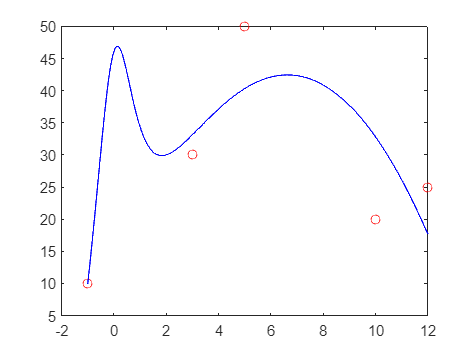

f=@(x) (coef(1)*x.^2 + coef(2)./(x.^2+1) + coef(3)*x);

xx = -1:0.01:12;
yy = f(xx);

plot(x, y, 'or', xx, yy, 'b')

Función de mathlab para ajustar un polinomio de cierto grado n

x = [-1 3 5 10 12]';
y = [10 30 50 20 25]';

% Polyfit: Halla un polinomio que se ajusta a los puntos dados
% Solo sirve para funciones polinomiales
% OJITO: La función es de grado máximo (n-1), donde n es #puntos,
% si se quisiera hallar de un grado mayor, solo devuelve una solución
% de las múltiples existentes
P = polyfit(x,y,4); 


xx = -1:0.01:12

xx =    -1.0000   -0.9900   -0.9800   -0.9700   -0.9600   -0.9500   -0.9400   -0.9300   -0.9200   -0.9100   -0.9000   -0.8900   -0.8800   -0.8700   -0.8600   -0.8500   -0.8400   -0.8300   -0.8200   -0.8100   -0.8000   -0.7900   -0.7800   -0.7700   -0.7600   -0.7500   -0.7400   -0.7300   -0.7200   -0.7100   -0.7000   -0.6900   -0.6800   -0.6700   -0.6600   -0.6500   -0.6400   -0.6300   -0.6200   -0.6100   -0.6000   -0.5900   -0.5800   -0.5700   -0.5600   -0.5500   -0.5400   -0.5300   -0.5200   -0.5100


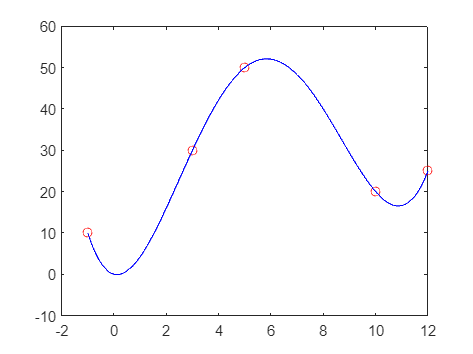


% Polyval: Evalúa el polinomio encontrado
yy = polyval(P,xx);

plot(x, y, 'or', xx, yy, 'b')

Linealización

x = [1 3 10 16]';
y = [4 7 12 8]';

X = x;
Y = log(y);

P = polyfit(X,Y,1);

m = P(2)

m = 1.6486

n = P(1)

n = 0.0434


A = n

A = 0.0434

C = exp(m)

C = 5.1997


fprintf("y = %f * e^%fx", C, A)

y = 5.199725 * e^0.043404x

Spline Natural

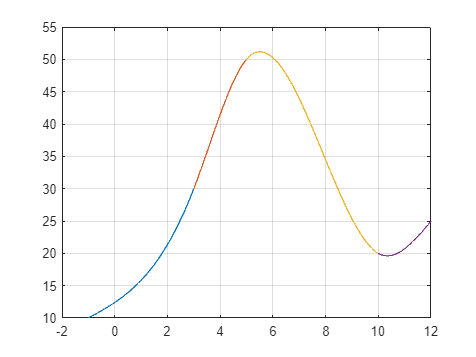

S =      347/1996         0           1107/499         10       
   -1365/1153      1041/499       5271/499         30       
     943/1639     -2945/587       2346/499         50       
    -601/998       1803/499      -2313/998         20       


x =        1       


y =        1       



ans =

  0×4 empty double matrix



x = [-1 3 5 10 12];
y = [10 30 50 20 25];
S = splinenatural(x,y)

function S = splinenatural(X, Y)
    N = length(X) - 1;
    H = diff(X);
    E = diff(Y) ./ H;
    diagprinc = 2 * (H(1:N-1) + H(2:N));
    diagsupinf = H(2:N-1);
    g0 = 0;
    gn = 0;
    A = diag(diagprinc) + diag(diagsupinf, 1) + diag(diagsupinf, -1);
    b = 6 * diff(E');
    g = A \ b;
    g = [g0 g' gn];
    S = zeros(N, 4);
    for i = 1:N
        S(i, 1) = (g(i + 1) - g(i)) / (6 * H(i));
        S(i, 2) = g(i) / 2;
        S(i, 3) = E(i) - H(i) * (g(i + 1) + 2 * g(i)) / 6;
        S(i, 4) = Y(i);
        xx = linspace(X(i), X(i + 1), 100);
        yy = S(i, 1) * (xx - X(i)).^3 + S(i, 2) * (xx - X(i)).^2 + S(i, 3) * (xx - X(i)) + S(i, 4);
        plot(xx, yy), hold on
    end
    grid on, hold off
end
